clear all
load('HDD_freqresp.mat');

### **PART (A)**

Ts = 1/50000;
s = tf('s');
G = HDD_freqresp;

Now adding time delay approximation,

sys1 = exp(-Ts*s/2);    

Add PI compensator. the zero is placed at 0.1 x wc = 2*pi*100 rad/s

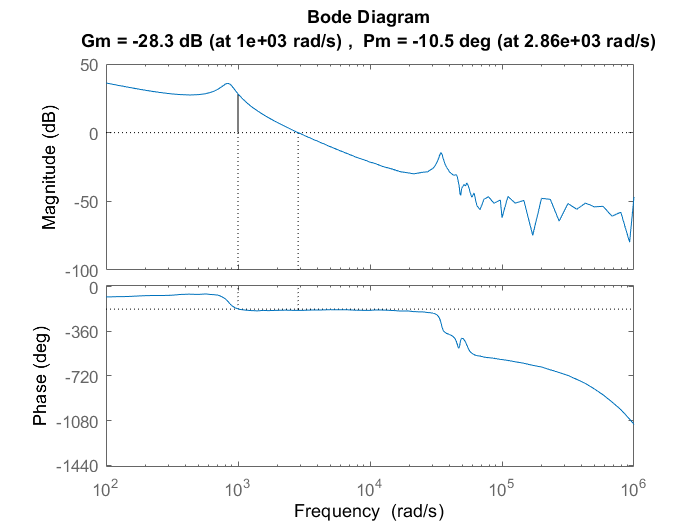

tf_intx = G*sys1*(s+100*2*pi)/s;
margin(tf_intx)

Since the bode plot was crossing the x-axis 2 times, I added a notch filter at the second crossing to obtain a single crossing at w = 1 KHz or 2*pi*1000 rad/s.

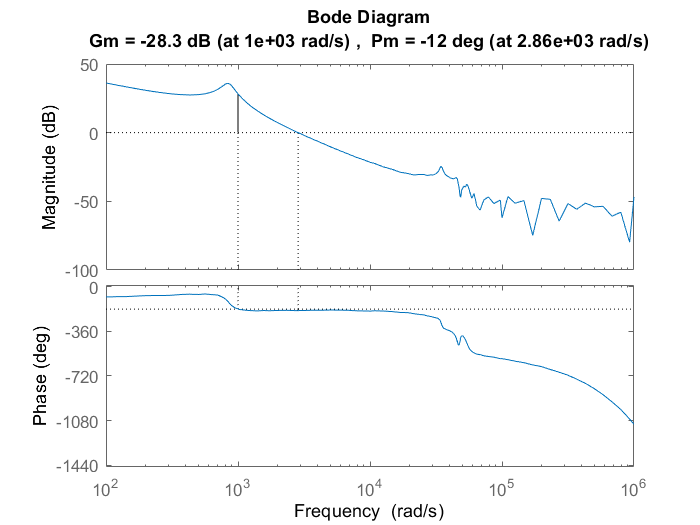

n = notch(10,5000,34300);
tf_intx = tf_intx*n;
margin(tf_intx)

Calculate the phase of the system at 1 KHz to add a lead compensator.

[m,phase,wout] = bode(tf_intx,2*pi*1000)

m = 0.1970

phase = 171.0884

wout = 6.2832e+03

phase_req = -135-phase

phase_req = -306.0884

L = lead(phase_req,2*pi*1000)

L =
 
    s + 2047
  ------------
  s + 1.929e04
 
Continuous-time transfer function.



New transfer function is now obtained which has the desired phase margin. 

TF = tf_intx*L;
[mag,phase,wout] = bode(TF,2*pi*1000)

mag = 0.0642

phase = -135.0804

wout = 6.2832e+03

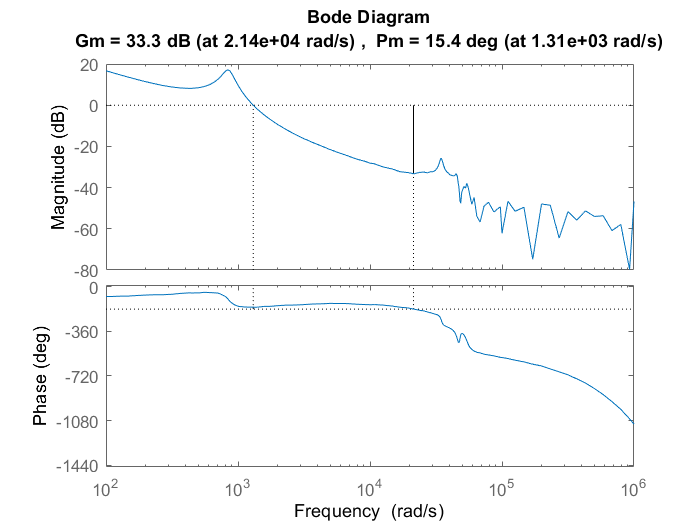

margin(TF)

Next, we calculate the magnitude at the desired cross-over frequency to provide an offset to the magnitude plot to achive the desired preformance.

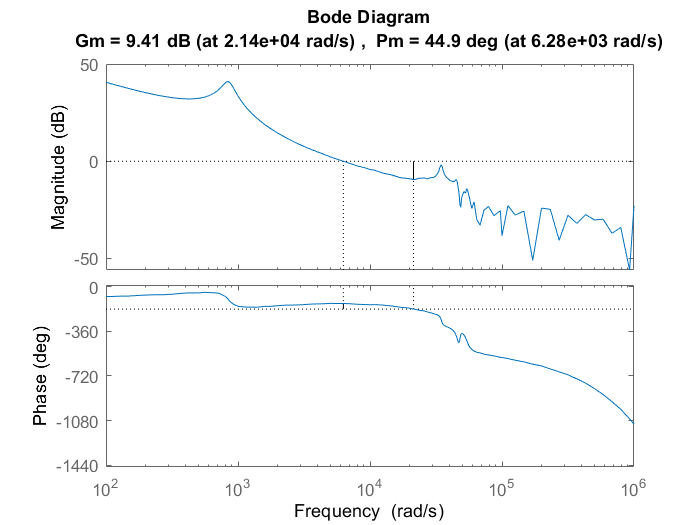

tf_final = TF/mag;
margin(tf_final)

### **PART (B)**

Compute the controller TF by multiplying all the above added compensators.

C = n*L*sys1*(s+100*2*pi)/(mag*s)

C =
 
                  s^4 + 7675 s^3 + 1.191e09 s^2 + 3.154e12 s + 1.513e15
  exp(-1e-05*s) * -----------------------------------------------------
                   0.06417 s^4 + 2252 s^3 + 9.507e07 s^2 + 1.456e12 s
 
Continuous-time transfer function.



Compute the Sensitivity and complementary sensitivity function using loopsens(). It can be alternatively done by the closed loop transfer funciton. S = I - CL_TF.

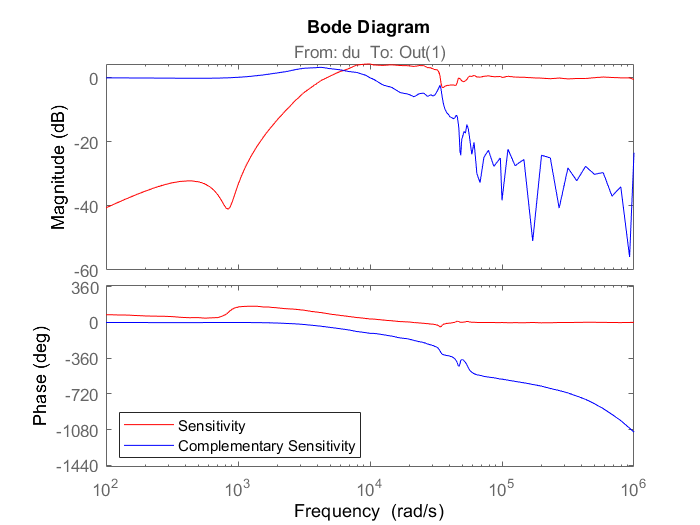

loops = loopsens(G,C);
bode(loops.Si,'r',loops.Ti,'b')
legend('Sensitivity','Complementary Sensitivity','Location','southwest')

Compute the peak gain of the Sensitivity funciton.

S_fn = loops.Si;
S_gpeak = getPeakGain(S_fn)

S_gpeak = 1.6440

Compute the peak gain of the Complementary Sensitivity funciton.

CS_fn = loops.Ti;
CS_gpeak = getPeakGain(CS_fn)

CS_gpeak = 1.4590

PART (C)

Assuming the number of states to be 8, the approximation of the FRD was obtained, and the bode plot is genereated.

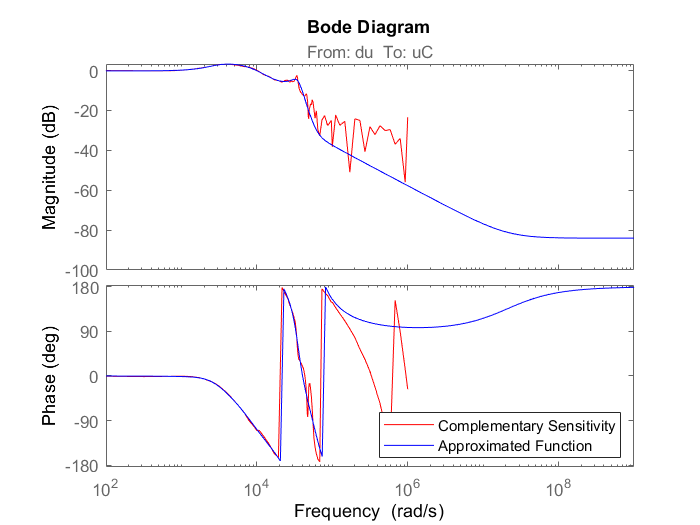

N = 8;
B = fitfrd(CS_fn,N);
opts = bodeoptions('cstprefs');
opts.PhaseWrapping = 'on';
bode(CS_fn,'r',B,'b',opts)
legend('Complementary Sensitivity','Approximated Function','Location','southeast')

Step response of the approximated complementary system.

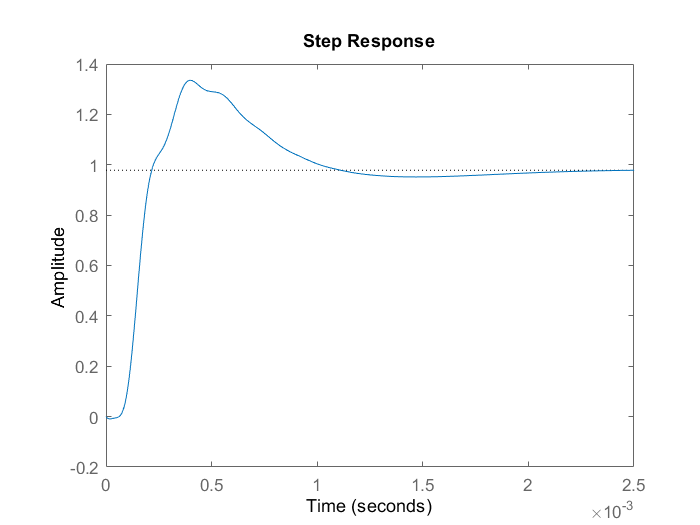

step(B)